# Lab03_Ben_Rotem

## q2

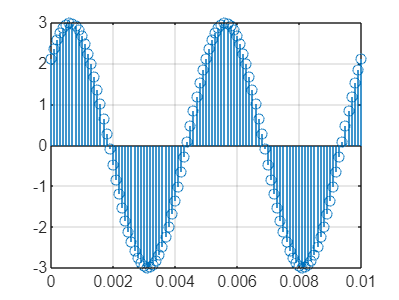

f0 = [200, 400, 800, 1000];
Fs = 10*10^3;
n1 = 0;
n2 = 100;
[tvec, xnTs] = single_singen(f0(1), 3, Fs, pi/4, n1, n2);
figure(1)
stem(tvec, xnTs);
grid on;

## q3

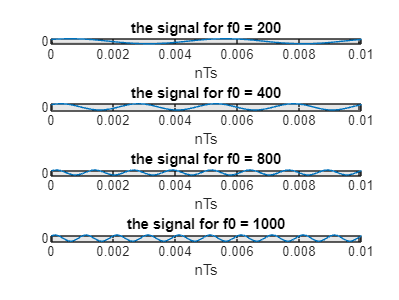

figure(2)
for i = 1:4
    [tvec,xnTs] = single_singen(f0(i), 3, Fs, pi/4, n1, n2);
    subplot(4,1,i);
    plot(tvec, xnTs);
    xlabel('nTs');
    ylabel('x(nTs)');
    title_vec = ['the signal for f0 = ', int2str(f0(i))];
    title(title_vec);
    grid on;
end

## q4

for i = 1:4
    [tvec, xnTs] = single_singen(f0(i), 3, Fs, pi/4, n1, Fs);
    soundsc(xnTs, Fs);
    pause(1);
    [tvec, xnTs] = single_singen(f0(i), 3, Fs, 0, n1, Fs); %%different phase
    soundsc(xnTs, Fs);
    pause(0.5);
end


## q5

output_signal = [];
for i = 1:4
    [tvec, xnTs] = single_singen(f0(i), 3, Fs, pi/4, n1, Fs);
    output_signal = [output_signal xnTs];
end
    soundsc(output_signal, Fs);
    pause(1);


## q6

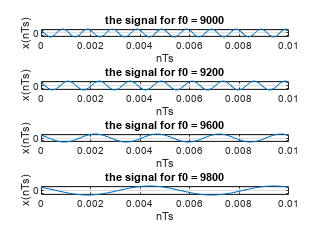

f0 = [9000, 9200, 9600, 9800];
figure(3)
output_signal = [];
for i = 1:4
    [tvec,xnTs] = single_singen(f0(i), 3, Fs, pi/4, n1, n2);
    output_signal = [output_signal xnTs];
    subplot(4,1,i);
    plot(tvec, xnTs);
    xlabel('nTs');
    ylabel('x(nTs)');
    title_vec = ['the signal for f0 = ', int2str(f0(i))];
    title(title_vec);
    grid on;
    soundsc(xnTs, Fs);
    pause(1);
    [tvec, xnTs] = single_singen(f0(i), 3, Fs, 0, n1, Fs); %%different phase
    soundsc(xnTs, Fs);
    pause(1);
end

soundsc(output_signal, Fs);
pause(0.5);

